clc
clear
close all
disp('recording...');

recording...


recObj = audiorecorder;
recordblocking(recObj,5);
disp('recorded');

recorded



disp('playing recorded sound...');

playing recorded sound...


play(recObj);
pause(7);

y = getaudiodata(recObj);
input= 'Counting-16-44p1-mono-15secs.wav';
disp('input sound')

input sound


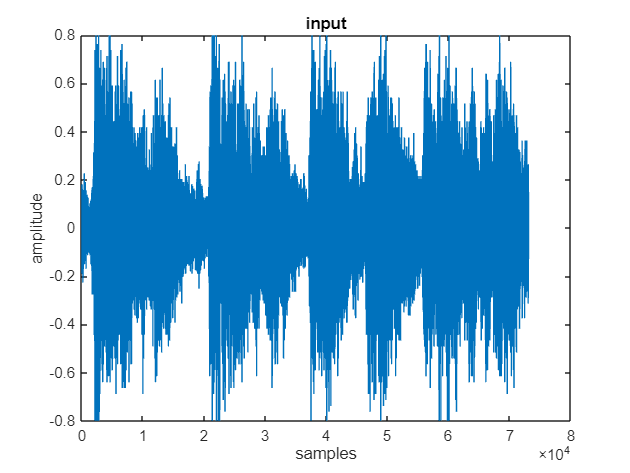

% input = 'audio.wav';
% [in,fs] = audioread(input);
% [y,fs] = audioread(input);
load handel.mat
fs=Fs;
y = y(:, 1);
info = audioinfo(input);
sound(y);
pause(10);
figure,plot(y);
title('input');
xlabel('samples');
ylabel('amplitude');

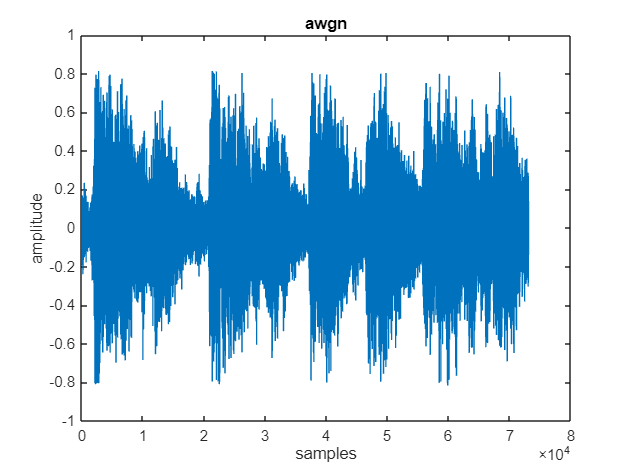

%%
y = awgn(y,40);
noi = y;
figure,plot(y);
xlabel('samples');
ylabel('amplitude');
title('awgn');

disp('playing added noise...');

playing added noise...


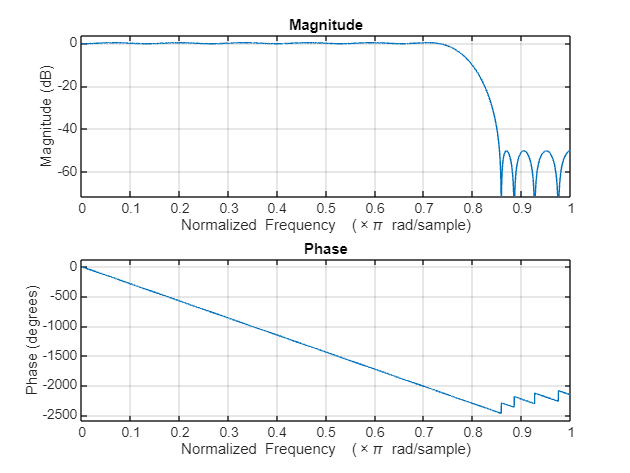

sound(y);
pause(10)
%%
%'Fp,Fst,Ap,Ast' (passband frequency, stopband frequency, passband ripple, stopband attenuation)
hlpf = fdesign.lowpass('Fp,Fst,Ap,Ast',3.0e3,3.5e3,0.5,50,fs);
D = design(hlpf);
freqz(D);

x = filter(D,y);
disp('playing denoised sound');

playing denoised sound


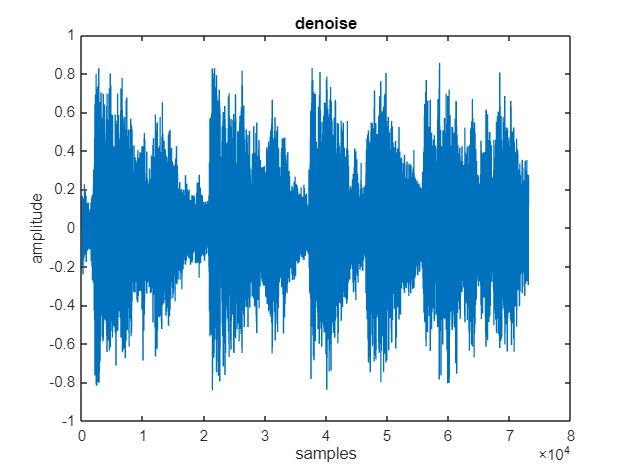

figure,plot(x);
title('denoise');
sound(x,fs);
xlabel('samples');
ylabel('amplitude');

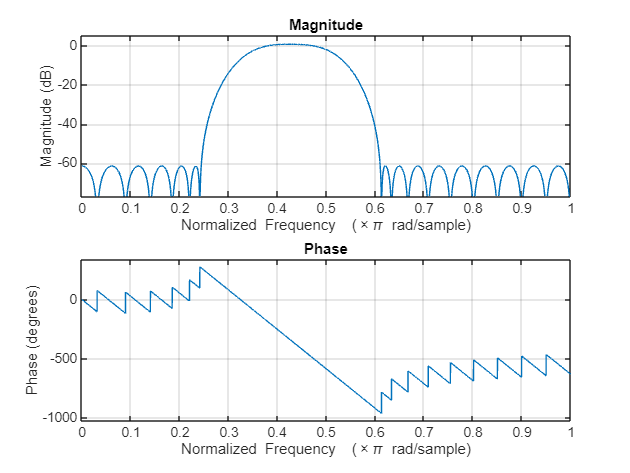

pause(10)
%% freq shaper using band pass
T = 1/fs;
len = length(x);
p = log2(len);
p = ceil(p);
N = 2^p;
f1 = fdesign.bandpass('Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2',2000,3000,4000,5000,60,2,60,2*fs);
hd = design(f1,'equiripple');
y = filter(hd,x);
freqz(hd);

y = y*100;
%%
disp('playing frequency shaped...');

playing frequency shaped...


sound(y,fs);
pause(10);
% amplitude shaper
disp('amplitude shaper')

amplitude shaper


out1=fft(y);
phse=angle(out1);
mag=abs(out1)/N;
[magsig,~]=size(mag);
threshold=1000;
out=zeros(magsig,1);
for i=1:magsig/2
    if(mag(i)>threshold)
        mag(i)=threshold;mag(magsig-i)=threshold;
    end
    out(i)=mag(i)*exp(j*phse(i));
    out(magsig-i)=out(i);
end
%
outfinal=real(ifft(out))*10000;
disp('playing amplitude shaped...');

playing amplitude shaped...


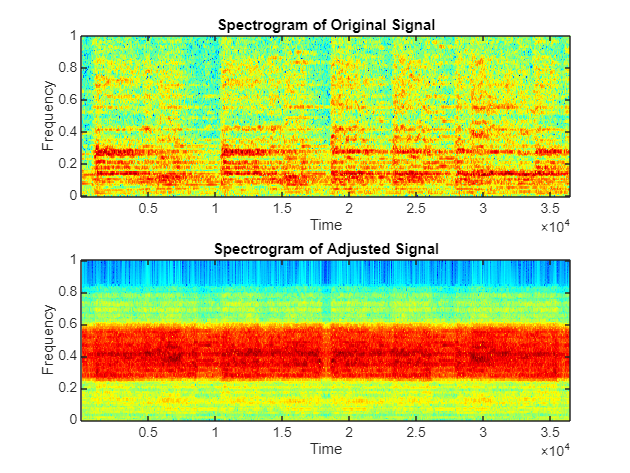

sound(outfinal,fs);
pause(10);

%
load handel.mat

figure;
subplot(2,1,1);
specgram(noi);
title('Spectrogram of Original Signal');

subplot(2,1,2);
specgram(outfinal);
title('Spectrogram of Adjusted Signal');